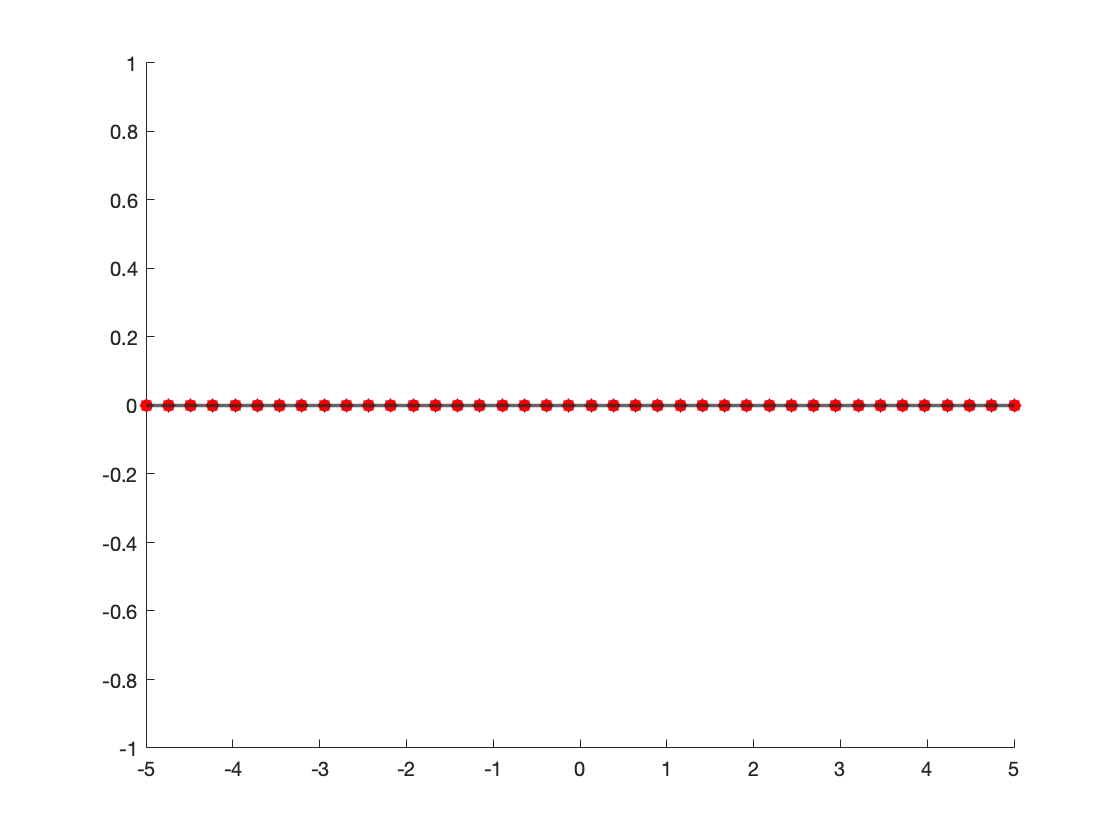

% Heisenberg model with NNN interactions

J1 = 1;
N = 6;

% compute Hessian
n = 40; % sampling J2 from -1 to 1;
n1 = 2^N; % consider the first n1 eigenstates with lowest energy
J2set = linspace(-5,5,n);




[X1,Y1,Z1] = PauliM(N,2);
sigmas = {X1,Y1,Z1};

E = zeros(1,n1);

Ms = zeros(3,3,n,n1);
lams = zeros(2^N,n);
for i = 1:n
    [H,spec,lam] = edH(J1,J2set(i),N);
    lams(:,i) = lam;
    for j = 1:n1
        E(j) = lam(j);
        vec = spec(:,j);
        
        for al = 1:3
            oa = sigmas{al};
            for be = 1:3
                sigmab = sigmas{be};
                % Ms(al,be,i,j) = vec'*sigmaa*(H-E(j)*eye(2^N))*sigmab*vec;
            end
        end
    end
end

eigspec = zeros(3*n1,n);
for i = 1:n
    A = [];
    for j = 1:n1
        M = Ms(:,:,i,j);
        [~,eigvals] = eig(M,"vector");
        A = [A;real(eigvals)];
    end
    eigspec(:,i) = A;
end

figure()
hold on
plot(J2set,eigspec,'b*')
plot(J2set,eigspec(40:48,:),'ro','MarkerFaceColor','r')
yline(0,'LineWidth',1.7)
hold off

% figure()
% plot(J2set,lams)

% plotting Hessian signatures w.r.t. the label of excited eigenstates
signs = zeros(n,n1);
for i = 1:n
    for j = 1:n1
        M = Ms(:,:,i,j);
        [~,eigvals] = eig(M,"vector");
        eigvals(abs(eigvals)<1e-7) = 0;
        signs(i,j) = sum(eigvals>0)-sum(eigvals<0);
    end
end
figure()

## Test for Heisenberg model *25 Sep 2023*

% check that the local Hamiltonians sums up to the global Hamiltonian in
% the case flagLocalHamiltonian = 'decomp'
J1 = 1; J2 = -0.5; N = 6;
[H,spec,lam] = edH(J1,J2,N);
flagLocalHamiltonian = 'canonical';

H1 = zeros(2^N,2^N);
for i = 1:N
    Hloc = HlocHeis(J1,J2,N,i,flagLocalHamiltonian);
    H1 = H1 + Hloc;
end

assert(or(isequal(H1,H),isequal(H1,2*H)),'local Hamiltonians does not yield correct global Hamiltonian');

n = 30; % # of samples of NNN interaction J2;
n1 = 2^N;

J2set = linspace(-2,2,n);
J1set = [1];
[X1,Y1,Z1] = PauliM(N,1);
sigmas = {X1,Y1,Z1};

eigspecFull = zeros(3*n1,n,length(J1set));


for ij1 = 1:length(J1set)
    J1 = J1set(ij1);
    
    Ms = zeros(3,3,n,n1);
    Ms1 = zeros(3,3,n,n1);
    for i = 1:n
        J2 = J2set(i);
        
        [H,spec,lam] = edH(J1,J2,N);
        
        Hloc = HlocHeis(J1,J2,N,1,flagLocalHamiltonian);
        for j = 1:n1
            E(j) = lam(j);
            vec = spec(:,j);
            for a = 1:3
                oa = sigmas{a};
                % check that the 1st order derivatives vanish
                % so that the state is indeed a Nash extreme
                assert(norm(vec'*(H*oa-oa*H)*vec)<1e-7, ...
                    'state not stationery wrt global Hamiltonian')
                assert(norm(vec'*(Hloc*oa-oa*Hloc)*vec)<1e-7, ...
                    'state not stationery wrt local Hamiltonian')
                
                for b = 1:3
                    ob = sigmas{b};
                    Ms(al,be,i,j) = vec'*oa*(H-E(j)*eye(2^N))*ob*vec;
                    %Ms1(al,be,i,j) = vec'*(2*oa*Hloc1*ob - oa*ob*Hloc1 - Hloc1*oa*ob)*vec;
                    
                end
                
            end
            
        end
    end
    
    eigspec = zeros(3*n1,n);
    for i = 1:n
        A = [];
        for j = 1:n1
            M = Ms(:,:,i,j);
            [~,eigvals] = eig(M,'vector');
            A = [A;real(eigvals)]; 
        end
        eigspec(:,i) = A;
    end
    
    eigspecFull(:,:,ij1) = eigspec;
end

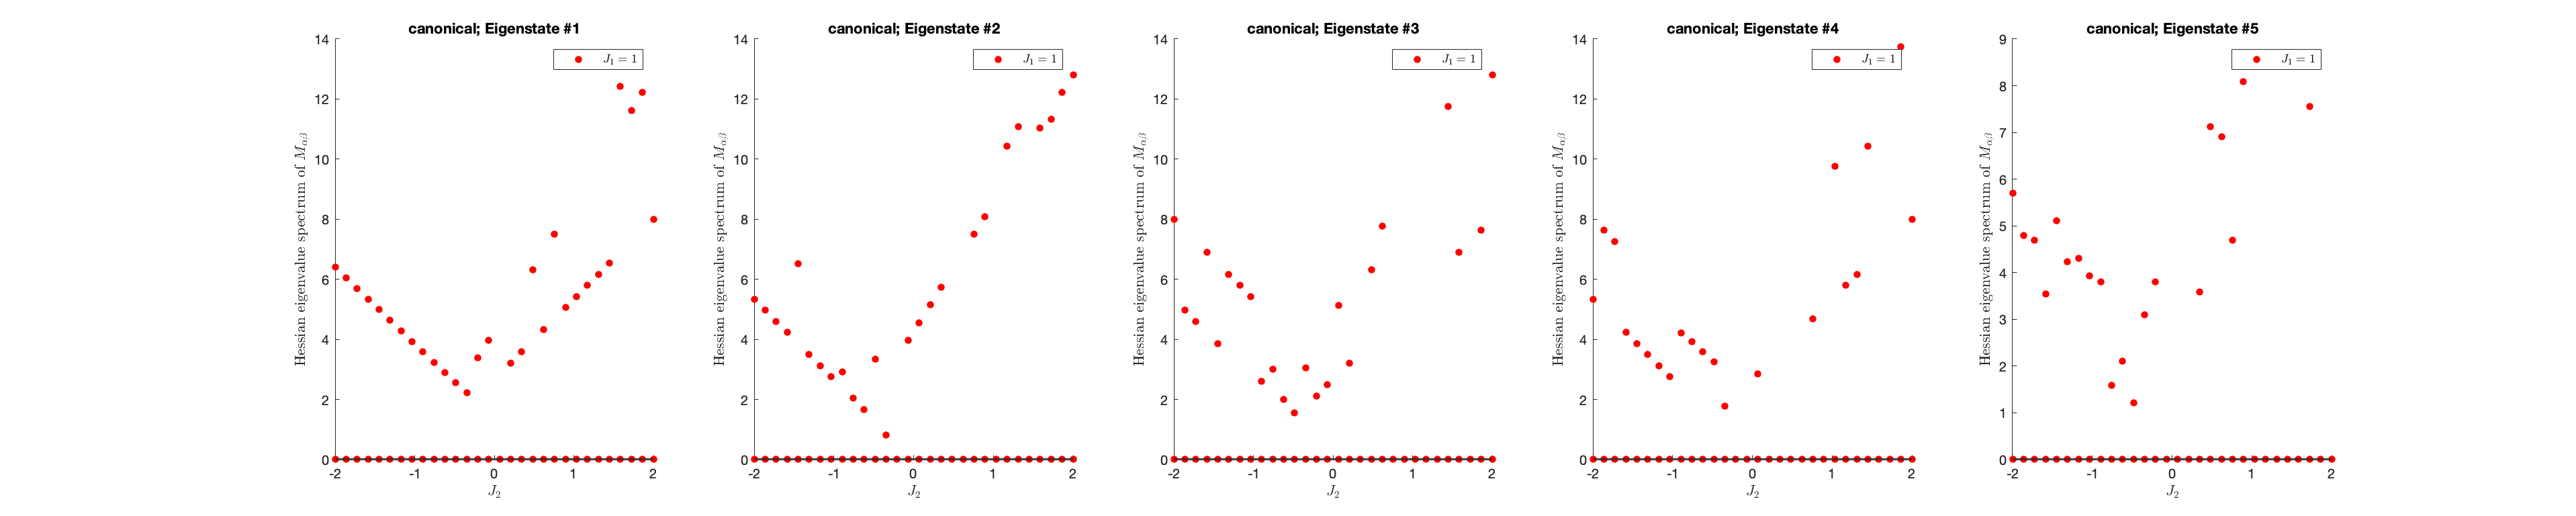

% plots using eigspecFull
nplot = 5;
stateplot = [1,2,3,4,5];
figure('Position',[500,500,400*nplot,400]);
colors = eye(3);

hold on
for i = 1:nplot
    subplot(1,nplot,i);
    hold on
    for ij1 = 1:length(J1set)
        eigspec = eigspecFull(:,:,ij1);
        plot(J2set,eigspec(3*(stateplot(i)-1)+1,:),'Marker','o','MarkerSize',5,'LineStyle',"none", ...
            'Color',colors(ij1,:),'MarkerFaceColor',colors(ij1,:),'DisplayName',['$J_1=$ ',num2str(J1set(ij1))]);
        plot(J2set,eigspec(3*(stateplot(i)-1)+2:3*stateplot(i),:),'Marker','o','MarkerSize',5,'LineStyle',"none", ...
            'Color',colors(ij1,:),'MarkerFaceColor',colors(ij1,:),'HandleVisibility','off');
    end
    yline(0,'LineWidth',1.7,'HandleVisibility','off')
    xlabel('$J_2$','Interpreter',"latex")
    ylabel('Hessian eigenvalue spectrum of $M_{\alpha \beta}$','Interpreter',"latex");
    % ylim([-2,10]);
    legend('Interpreter','latex');
    title([flagLocalHamiltonian,'; Eigenstate #',num2str(stateplot(i))]);
    hold off
end

N = 6; J1 = 1; J2 = -0.6;
[H1,spec,lam] = edH(J1,J2,N)

H1 =   -2.400000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0               

spec =                    0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.000000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0             

lam =   -6.400000000000003
  -5.922499389946285
  -5.922499389946282
  -5.922499389946281
  -5.922499389946281
  -5.922499389946278
  -5.922499389946277
  -5.600000000000001
  -5.599999999999999
  -5.599999999999997


function [H,spec,lam] = edH(J1,J2,N)
% exact diagonalization for NNN Heisenberg model
X = [0,1;1,0];
Y = 1i * [0,-1;1,0];
Z = [1,0;0,-1];


% H1 = -(J1*IIlocInt(1,X,N)+J1*IIlocInt(1,Y,N)+J1*IIlocInt(1,Z,N));
% H2 = -(J2*IIlocInt(2,X,N)+J2*IIlocInt(2,Y,N)+J2*IIlocInt(2,Z,N));
H1 = -(J1*IIlocInt1(1,X,N)+J1*IIlocInt1(1,Y,N)+J1*IIlocInt1(1,Z,N));
H2 = -(J2*IIlocInt1(2,X,N)+J2*IIlocInt1(2,Y,N)+J2*IIlocInt1(2,Z,N));
H = H1+H2;
[spec,lam] = eig(H,'vector');

% [lamSort,lamOrder] = sort(lam);
% specSort = spec(:,lamOrder);
% 
% spec = specSort;
% lam = lamSort;

end


function [H] = IIlocInt(dij,op,N)
% Creating 2-local terms for N-site spin-1/2 Hamiltonians
% soecifically for N-th neighbour interactions
I = eye(2);
H = zeros(2^N);
for i = 1:N
    if i > N-dij
        j = i-N+dij;
    else
        j = i+1;
    end
    h = 1;
    for l = 1:N
        if and(l~=i,l~=j)
            h = kron(h,I);
        else
            h = kron(h,op);
        end
    end
    H = H + h;
end

end

function H = IIlocInt1(n,op,N)
% Creating 2-local terms for N-site spin-1/2 Hamiltonians
% specifically for n-th neighbour interactions
% with coefficients
I = eye(2);
H = zeros(2^N);

for i = 1:N
    jl = mod(i-1-n,N)+1;
    jr = mod(i-1+n,N)+1;
    
    tmp = 1;
    for l = 1:N
        switch l
            case {jl,i}
                tmp = kron(tmp,op);
            otherwise
                tmp = kron(tmp,I);
        end
    end
    H = H + 1/2*tmp;
    tmp = 1;
    for l = 1:N
        switch l
            case {jr,i}
                tmp = kron(tmp,op);
            otherwise
                tmp = kron(tmp,I);
        end
    end
    H = H + 1/2*tmp;
end
end

function [Xi,Yi,Zi] = PauliM(N,i)
X = [0,1;1,0];
Y = 1i * [0,-1;1,0];
Z = [1,0;0,-1];
I = eye(2);

Xi = 1;
Yi = 1;
Zi = 1;
for j = 1:N
    if j~=i
        Xi = kron(Xi,I);
        Yi = kron(Yi,I);
        Zi = kron(Zi,I);
    else
        Xi = kron(Xi,X);
        Yi = kron(Yi,Y);
        Zi = kron(Zi,Z);
    end
end

end

function [Hloc] = HlocHeis(J1,J2,N,i,flagLocalHamiltonian)
% create ith local term for Heisenberg model
% priorotizing either summation or NE

X = [0,1;1,0];
Y = 1i * [0,-1;1,0];
Z = [1,0;0,-1];
I = eye(2);

switch flagLocalHamiltonian
    case 'decomp'
        a = 1/2;
    case 'canonical'
        a = 1;
end

Hloc = zeros(2^N,2^N);
J = [J1,J2];
% n^th NN interaction
for iNN = 1:2
    jl = mod(i-1-iNN,N)+1;
    jr = mod(i-1+iNN,N)+1;
    
    tmpl = cell(1,3);
    for l = 1:3
        tmpl{l} = 1;
    end
    for l = 1:N
        switch l
            case {jl,i}
                tmpl{1} = kron(tmpl{1},X);
                tmpl{2} = kron(tmpl{2},Y);
                tmpl{3} = kron(tmpl{3},Z);
            otherwise
                tmpl{1} = kron(tmpl{1},I);
                tmpl{2} = kron(tmpl{2},I);
                tmpl{3} = kron(tmpl{3},I);
        end
    end
    Hloc = Hloc - a*J(iNN)*(tmpl{1}+tmpl{2}+tmpl{3});
    
    tmpr = cell(1,3);
    for l = 1:3
        tmpr{l} = 1;
    end
    for l = 1:N
        switch l
            case {jr,i}
                tmpr{1} = kron(tmpr{1},X);
                tmpr{2} = kron(tmpr{2},Y);
                tmpr{3} = kron(tmpr{3},Z);
            otherwise
                tmpr{1} = kron(tmpr{1},I);
                tmpr{2} = kron(tmpr{2},I);
                tmpr{3} = kron(tmpr{3},I);
        end
    end
    Hloc = Hloc - a*J(iNN)*(tmpr{1}+tmpr{2}+tmpr{3});
end

end